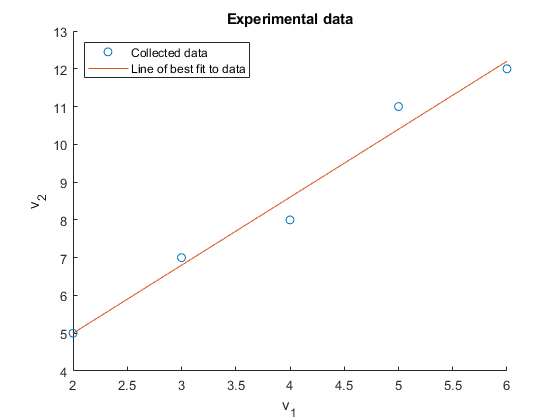

% MATLAB TEST QUESTION 3

% initializing vectors containing data collected from experiment
v1 = 2 : 6;
v2 = [5 7 8 11 12];

% setting up A matrix and b vector
A = ones(length(v1), 2);
A(:,2) = v1';
b = v2';

% finding coefficients of the line of best fit
coeffs = LSsolver(A, b);


% plotting experimental data points
scatter(v1, v2)
hold on

% plotting line of best fit
best_fit = coeffs(1) + (coeffs(2).*v1);
plot(v1, best_fit)

title('Experimental data')
xlabel('v_1')
ylabel('v_2')
legend('Collected data', 'Line of best fit to data', "Location", "northwest")

function [coeffs] = LSsolver(A, b)
    A_star = A'*A;   % let A_star be transpose(A)*A
    b_star = A'*b;   % let b_star be transpose(A)*b
    coeffs = (inv(A_star)*b_star)';    % LS estimates obtained by inverse(A_star)*b_star
end

The coefficients of the line of best fit are: c_1 = 1.4 and c_2 = 1.8 so the straight line model is:

v_2 = 1.4 + 1.8v_1

v_2(v_1=4.6) = 1.4 + 1.8(4.6) = 9.68

Therefore I estimate that the value of v_2 corresponding to v_1 = 4.6 is 9.68.